% declare constants
DIM = 3;
SAMPLES = 10000;
SIMULATE = 1000;
% set seed 
rng(4864)

% Test that the Q function is working correctly
test_Q = simulate_Q(eye(DIM), SAMPLES);

res = zeros(1, size(test_Q, 3));
for i=1:size(test_Q, 3)
    res(1, i) = orthogonal(test_Q(:,:,i));
end

% if this equals 1 then the funciton is working
all(res)

ans = logical
   1


% get the approximate integral of the trace function
[expected, allT] = expected_trace(test_Q);
expected

expected = 0.0170

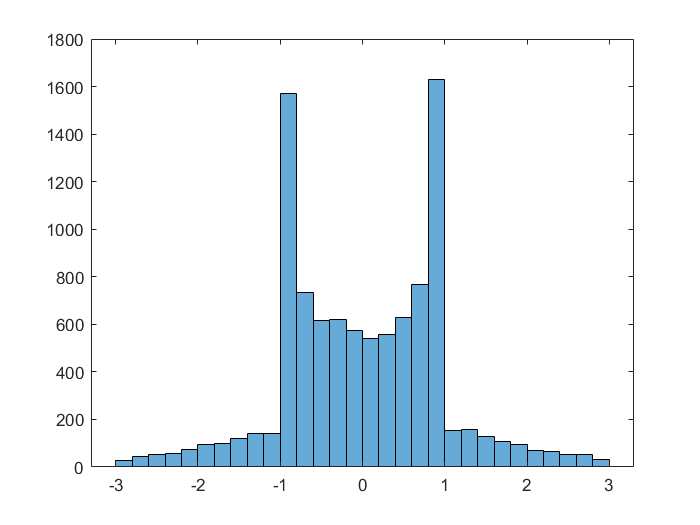

histogram(allT)

build a distribution of the mean trace from each simulation of the markov chain

    hopefully norm distributed --> normal approx 

var(tr)

sim1 = simulate_traces(SIMULATE, DIM, SAMPLES);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


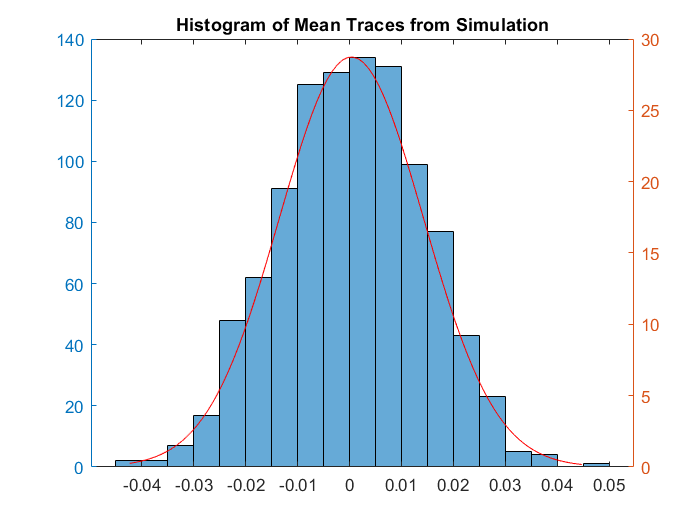

clf;
title("Histogram of Mean Traces from Simulation")
yyaxis left
histogram(sim1)
hold on 
yyaxis right
x = min(sim1):0.001:max(sim1);
y = normpdf(x, mean(sim1), sqrt(var(sim1)));
plot(x, y, 'r')

mean(sim1)

ans = 3.6918e-04

var(sim1)

ans = 1.9268e-04

prctile(sim1, [2.5, 97.5])

ans =    -0.0256    0.0267


% normal approximation bootstrap
alpha = 0.05;
[mean(sim1) - norminv(1 - alpha / 2) * std(sim1), mean(sim1) + norminv(1 - alpha / 2) * std(sim1)]

ans =    -0.0268    0.0276


bootstrap interval

    generate 1 markov chain

    resample, calcualte tr on sample

    tr1,..,trn --> thetha_0 --> quartiles

test_Q = simulate_Q(eye(DIM), SAMPLES);
[expected, all_trace] = expected_trace(test_Q);
original_estimate = mean(all_trace);
boot_data = stat_star(all_trace, @mean, 10000);
boot_CI = [original_estimate - prctile(boot_data - original_estimate, 97.5), ...
    original_estimate - prctile(boot_data - original_estimate, 2.5)];
boot_CI

boot_CI =     0.0094    0.0475


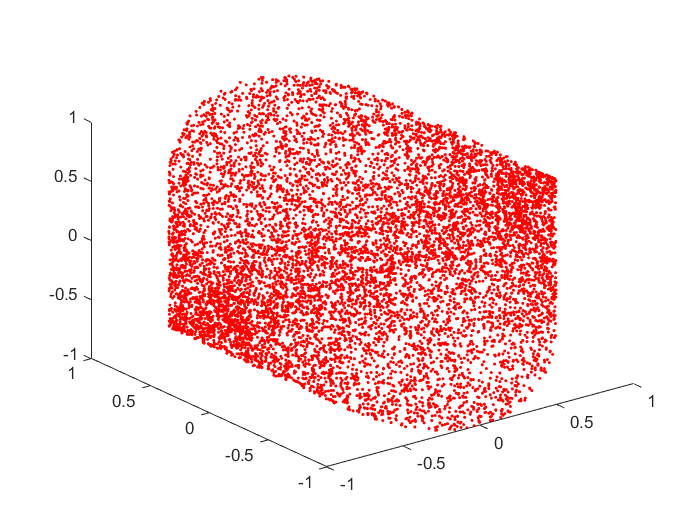

% visualizing the different indexes of the data
clf;
plot3(squeeze(test_Q(1,1,:)), squeeze(test_Q(1,2,:)), squeeze(test_Q(2,1,:)),'r.')

looking at differnt dimension e.g. look at plot of (1,1) index vs (1,2) index reveals different structures

Some plots are circular and some are square

This is for the second method

https://jarrodmcclean.com/integrating-over-the-unitary-group/

test_Q2 = random_unitary(DIM, SAMPLES);
res2 = zeros(1, size(test_Q2, 3));
for i=1:size(test_Q2, 3)
    res2(1, i) = orthogonal(test_Q2(:,:,i));
end
all(res2)

ans = logical
   1


[expected2, allT2] = expected_trace(test_Q2);
expected2

expected2 = -0.0036

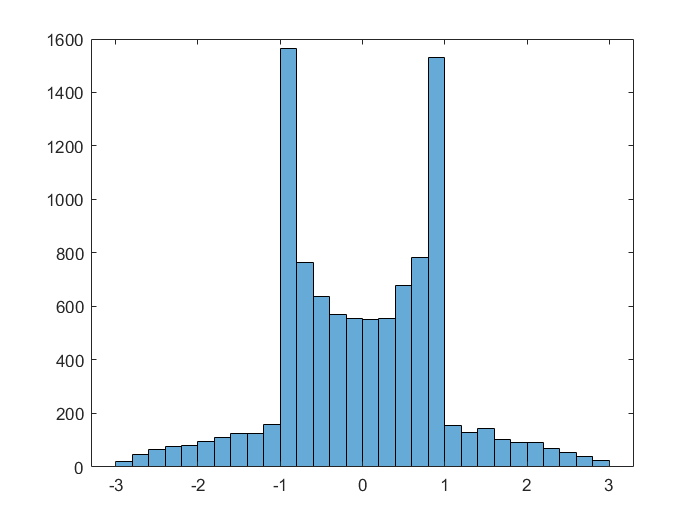

histogram(allT2)

sim2 = simulate_traces_method2(SIMULATE, DIM, SAMPLES);

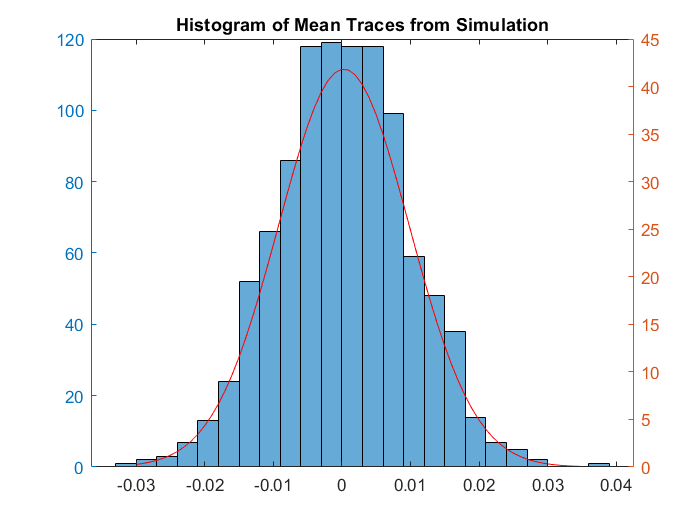

clf;
title("Histogram of Mean Traces from Simulation")
yyaxis left
histogram(sim2)
hold on 
yyaxis right
x = min(sim2):0.001:max(sim2);
y = normpdf(x, mean(sim2), sqrt(var(sim2)));
plot(x, y, 'r')

mean(sim2)

ans = 2.8421e-04

var(sim2)

ans = 9.0909e-05

prctile(sim2, [2.5, 97.5])

ans =    -0.0182    0.0189


% normal approximation bootstrap
alpha = 0.05;
[mean(sim2) - norminv(1 - alpha / 2) * std(sim2), mean(sim2) + norminv(1 - alpha / 2) * std(sim2)]

ans =    -0.0184    0.0190


test_Q2 = random_unitary(DIM, SAMPLES);
[expected2, all_trace2] = expected_trace(test_Q2);
original_estimate2 = mean(all_trace2);
boot_data2 = stat_star(all_trace2, @mean, 10000);
boot_CI2 = [original_estimate2 - prctile(boot_data2 - original_estimate2, 97.5), ...
    original_estimate2 - prctile(boot_data2 - original_estimate2, 2.5)];
boot_CI2

boot_CI2 =    -0.0136    0.0257


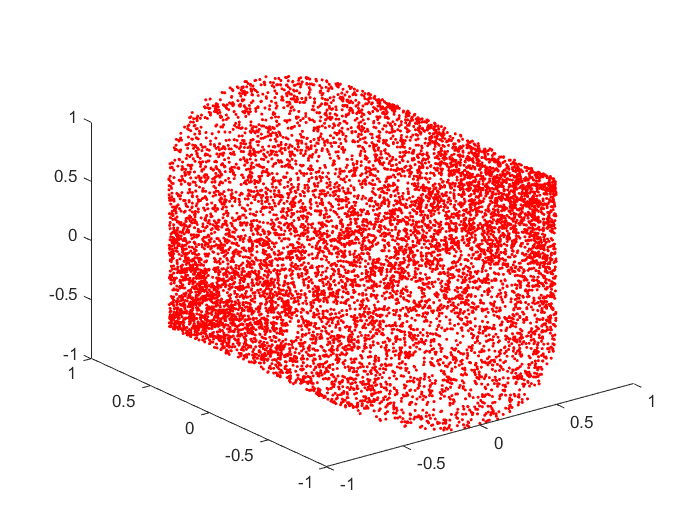

% visualizing the different indexes of the data
clf
plot3(squeeze(test_Q2(1,1,:)), squeeze(test_Q2(1,2,:)), squeeze(test_Q2(2,1,:)),'r.')